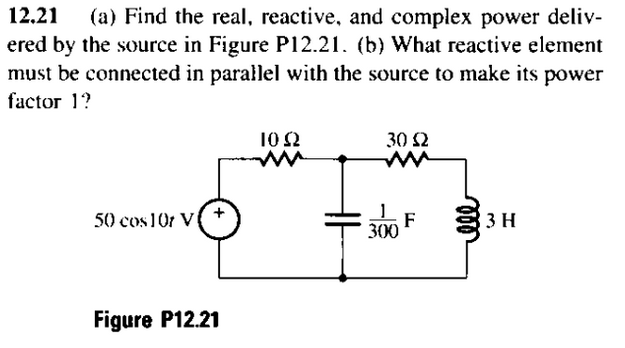

primero convertimos todo  aimpedancias

clc, clear, close all
format short g

vf = 50;
w = 10;
f = w/(2*pi);
c = 1/300;
l = 3;

z1 = 10;
z2 = (1/(j*w*c));
z3 = 30;
z4 = j*w*l;

reducimos impedancias

zeq = 1/((1/(z3+z4))+(1/z2)) + z1 % impedancia equivalente[omhs] carga capacitiva

zeq =            40 -         30i


If = vf/zeq % corriente [A]

If =           0.8 +        0.6i


S = vf*conj(If)*0.5 % potencia compleja [VAR]

S =            20 -         15i


Ahora calculamos el factor de potencia:

fp = cos(atan(imag(S)/real(S))) %en adelanto

fp =           0.8


como el factor de potencia esta en adlanto sabemos que se conectará un elemento inductivo:

xp = ((real(zeq)^2)+(imag(zeq)^2))/(real(zeq)*tan(-acos(1))-imag(zeq))*j %

xp =             0 +     83.333i


verificamos el nuevo factor de potencia:

lp = xp/(j*w) % inductancia en paralelo a la fuente

lp =        8.3333



zeq1 = 1/((1/zeq)+(1/(xp)))

zeq1 =          62.5


If = vf/zeq1

If =           0.8


S = vf*conj(If)

S =     40


fp = real(S)/abs(S)

fp =      1


Vemos que se ha corregido el factor de potencia, lo verificamos en el simulador: